# Kalman Filter -- Cap 4

A ideia desse reporte é apresentar o caso do Filtro de Kalman. Estou seguindo a ideia apregoada no livro do Zarchan (*Fundamentals of Kalman Filtering: A Pratical Approach*). Nisso eu irei direto ao problema no tempo contínuo e depois simplifico para o caso em que a gente discretiza o sistema.

Seja, então, a descrição da física do problema espressa na Espaço de Estados a tempo contínuo:


$$\dot{x} = Ax + Bu + w
$$


em que $w$ é um ruído branco do processo. Existe uma matriz associada ao ruído $w$, tal que:


$$Q = E[ww^T]$$


Não existe um significado físico para essa matriz, mas a gente verá no futuro que ela está relacionada ao desconhecimento que temos a respeito do processo em si (afinal, não há como representar com 100% de certeza uma dinâmica). 

O Filtro de Kalman necessita que tenhamos as medidas físicas relacionadas com a seguinte equação:


$$y = Cx + v$$


em que $y$ diz respeito ao vetor de medidas, $C$é a matriz de medidas e $v$é o ruído branco de medida. Existe uma matriz associada ao ruído $v$, tal que:


$$R = E[vv^T]$$


Para utilizarmos o Filtro de Kalman, precisamos discretizar esse sistema expresso a tempo contínuo. Para o sistema, tem-se que:


$$\Phi(t) = \mathcal{L}^{-1}[(sI-A)^{-1}]
$$


Discretizando a matriz $\Phi \text{ }\left(t\right)$ sistema, tem-se que:


$$\Phi_{k} = \Phi(T_{s})$$


em que $T_s$ é o período de amostragem. Além do mais, na discretização da nossa amotra, tem-se que:


$$y_{k} = Cx_k + v_k
$$


e


$$R_k = E[v_kv_k^T]$$


A resultante do Filtro de Kalman é dado por:


$$\hat{x}_{k} = \Phi_k \hat{x}_{k-1} + B_{k}u_{k-1} + K_{k}[y_{k} - H(\Phi_{k}\hat{x}_{k-1}+B_{k}u_{k-1})]$$


em que $u_{k-1}$ é assumido constante entre as amostras, $K_k$ é o ganho de Kalman no instante $k$ e a matriz $B_k$ é dado por:


$$B_{k} = \int_{0}^{T_s}\Phi({\tau})\textbf{B}d\tau$$


Os ganhos de Kalman são computados por meio da matriz de Riccati. As equações são recursivas:


$$M_k = \Phi_{k}P_{k-1}\Phi_{k}^T + Q_k
$$



$$K_k = M_{k}C^T(CM_kC^T+R_k)^{-1}$$



$$P_k = (I-K_kC)M_k$$


em que:


$$Q_k = \int_{0}^{T_s}\Phi(\tau)\textbf{Q}\Phi^{T}(\tau) d\tau$$


Para iniciar as equações de Riccati a gente precisa inicializar a matriz com algum $P_0$.

Olhando de maneira estrita, o que a gente tem é que:

$\bullet$a matriz $M_k$ diz respeito à matriz de Covariância representando os erros das estimativas dos estados antes da atualização;

$\bullet$a matriz $P_k$ diz respeito à matriz de Covariância representando os erros das estimativas dos estados depois da atualização.

O que a equação do Filtro de Kalman faz é simplesmente tomar uma estimativa e corrigir essa estimativa com base nos dados reais amostrados. Sendo assim, tomemos um exemplo.

## Exemplo:

Imagine o caso em que desejamos estimar a posição e velocidade de um objeto caindo. Ele inicialmente apresenta altitude de 400.000 $\mathrm{ft}$ e velocidade inicial de 6.000 $\frac{\mathrm{ft}}{s}$ em direção ao um radar posicionado no solo (ou seja, caindo). Neste exemplo não se considera o efeito do arrasto e a aceleração da gravidade é g = 32,2 $\frac{\mathrm{ft}}{s^2 }$ . Vamos assumir que as medidas obtidas pelo radar são ruidosas, apresentando as mesmas um desvio padrão de 1.000 ft com média zero. Neste exemplo considera-se que o radar faz amostragem na taxa de 10Hz (ou seja, 10 amostras em 1 s) durante 30 s. A ideia é construir um Filtro de Kalman para estimar a posição e velocidade do objeto a medida que ele cai e são coletadas informações pelo radar.

Pela física de Newton, sabe-se que a altura de um objeto que cai com as características apresentadas é dada por:


$$x = 400000- 6000 - gt^2/2$$


a velocidade é:


$$\dot{x} = 6000 - gt
$$


Cadastrando os itens descritos, tem-se:

x0 = 400000;        % altura inicial
v0 = 6000;          % velocidade inicial
g  = 32.2;          % gravidade.

Do jeito que foi abordado no início do processo, tem-se:

Ttotal = 30;   % Tempo total de amostragem.
fs     = 10;   % Frequência de amostragem.
t      = linspace(0, Ttotal, (fs*Ttotal + 1));        % Instantes de amostragem.

O objeto em queda terá, dada as condições do problema proposto, o seguinte comportamento:

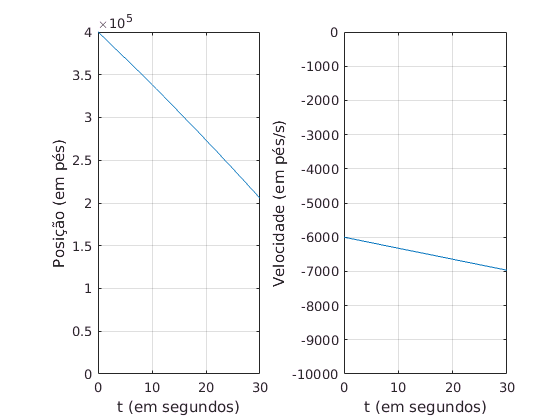

% Posição.
for i = 1:(fs*Ttotal + 1)
    x(i) = x0 - v0*t(i) - 0.5*g*(t(i)^2);        
end
% Velocidade.
v = -v0 - g*t;   

% Plota os resultados de posição e velocidade.
subplot(1, 2, 1);
plot(t, x); grid; 
xlabel('t (s)');
ylabel('Posição (pés)');
axis([0 Ttotal 0 400000]);

subplot(1, 2, 2);
plot(t, v); grid;
xlabel('t (s)');
ylabel('Velocidade (pés/s)');
axis([0 Ttotal -10000 0]);

O radar (dispositivo que fará as medições do sistema) apresenta um desvio padrão de 1000 ft com média zero. Dessa forma, as medidas do radar estarão corrompidas com erro (o que será denotado por ruido):

desvio_padrao = 1000;                                 % em pés.
ruido = 0 + desvio_padrao*randn(fs*Ttotal + 1, 1);    % de medida pelo radar.
ruido = ruido';                            

 Isso significa dizer que a medida do radar será a medida real corrompida com ruido. Sendo assim, Tem-se que:

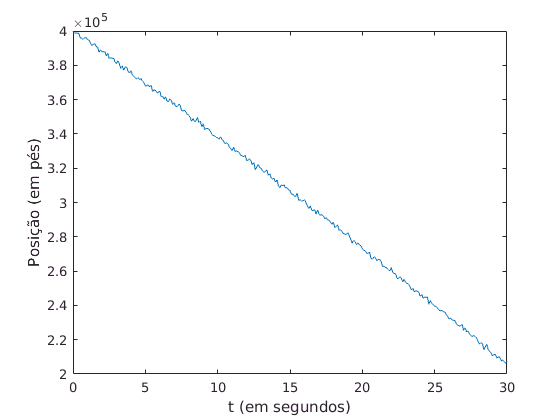

% Sinal MEDIDO pelo radar com ruído (posição apenas).
y = x + ruido;
figure;
plot(t, y);
grid;

xlabel('t (s)');
ylabel('Posição (pés)');

Vamos agora montar o problema do jeito que preconiza o Filtro de Kalman. 

O meu sistema no final das contas apresenta uma interessante forma de apresentação, pois tem-se que um objeto caindo sofrerá apenas ação da gravidade:


$$\ddot{x}(t) = -g$$


E assim, derivando-se essa aceleração (constante), tem-se que:


$$\frac{{\text{d}}^3 }{\text{d}t^3 }x\left(t\right)=0$$


Então, a gente consegue escrever o sistema no seguinte formato:


$$\left\lbrack \begin{array}{c}
\frac{\text{d}}{\text{d}t}x\\
\frac{{\text{d}}^2 }{\text{d}t^2 }x\\
\frac{{\text{d}}^3 }{\text{d}t^3 }x
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0 & 1 & 0\\
0 & 0 & 1\\
0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\dot{x\text{ }} \\
\ddot{\text{ }x} 
\end{array}\right\rbrack$$


Significa dizer então que a matriz B = 0 e a matriz A é a que está logo acima.

Sendo assim, temos de determinar quem é a matriz $\Phi \left(t\right)$ para depois discretizá-la.

% Matriz A do sistema (contínuo).
A = [0 1 0;
     0 0 1;
     0 0 0];
B = [0; 0; 0];

% Calcular a inversa de Laplace.
syms s

I     = eye(3);  % Matriz identidade de ordem 3.
phi_t = ilaplace((s*I - A)^(-1))

$$phi\_t = \left(\begin{array}{ccc} 1 & t & \frac{t^{2}}{2}\\ 0 & 1 & t\\ 0 & 0 & 1 \end{array}\right)$$

Quanto a gente discretiza o sistema para um $T_s$ conforme especificado, tem-se que:

% Matriz de estados.
Ts    = 1/fs;              % Tempo de amostragem.
phi_k = [1    Ts (Ts^2)/2;
         0     1    Ts;
         0     0    1];
     
% Vocẽ poderia também fazer de forma mais inteligente por meio do comando abaixo:
% phi_k = subs(phi_t, Ts);

Vamos agora determinar a matriz Q a tempo discreto. Importante saber quem é a mesma, em tempo contínuo é dada por:


$$Q=E\left\lbrack {\mathrm{ww}}^T \right\rbrack$$


Como não há erro de processo envolvido no sistema (ou seja, é considerada essa situação), a nossa matriz $Q$ será nula e quadrada de ordem 3. Quando a gente coloca essa matriz para determinação da matriz $Q_k$ dará no final uma matriz nula, quadrada e de ordem 3 (só verificar nas equações). Isso pode ser comprovado substituindo Q nula na equação abaixo:


$$Q_k = \int_{0}^{T_s}\Phi(\tau)\textbf{Q}\Phi^{T}(\tau) d\tau$$


Assim, tem-se que:

Q   = zeros(3,3);

% 1) Uma forma de fazer (sendo direto).
% Q_k = zeros(3,3);

% 2) Podemos também fazer no 'brute force', Para tal, tem-se que:
PRODUTO = phi_t * Q * (phi_t');
Q_k     = int(PRODUTO, [0 Ts]);


Olhando o tipo de medida que iremos ter, o radar mede apenas a distância do objeto. Sendo assim, a matrix C do sistema terá apenas uma únia entrada.

C = [1 0 0];

O desvio padrão do ruído de medida é dado de tal forma que temos que determinar a matriz $R_k \ldotp$ Sendo assim, tem-se que o ruído será equivalente ao erro característico do radar.

R_k = desvio_padrao^2;

O nosso sistema está todo resolvido. Precisamos apenas iniciar o processo do Filtro de Kalman e rodar a simulação.

% Inicialização do sistema de Kalman.
P{1}  = 999999999*eye(3);

% Estimativas iniciais dos estados do sistema.
x_hat{1} = [0; 0; 0];

Executo a recursão do Filtro de Kalman.

% Recursão de Kalman.
for k = 2:max(size(x))
    
    % Equação de Riccati.
    M{k} = (phi_k) * P{k-1} * (phi_k') + Q_k;
    K{k} = M{k} * (C') * inv(C * M{k} * (C') + R_k);
    P{k} = (I - K{k}*C)*M{k};
    
    % Atualização dos estados.
    x_hat{k} = phi_k*x_hat{k-1} + K{k}*(y(k) - C*phi_k*x_hat{k-1});
end

% Separa os resultados para facilitar o plot.
for i = 1:max(size(x))
   x_end(i)   = x_hat{i}(1,1); 
   xd_end(i)  = x_hat{i}(2,1);
   xdd_end(i) = x_hat{i}(3,1);
end

Agora eu ploto todo o sistema.

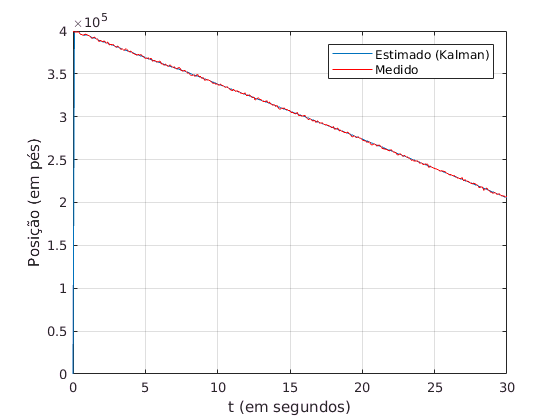

figure;
plot(t, x_end, t, y, 'r')
legend('Estimado (Kalman)', 'Medido');
xlabel('t (s)');
ylabel('Posição (pés)');
grid;
axis([0 Ttotal 0 400000])

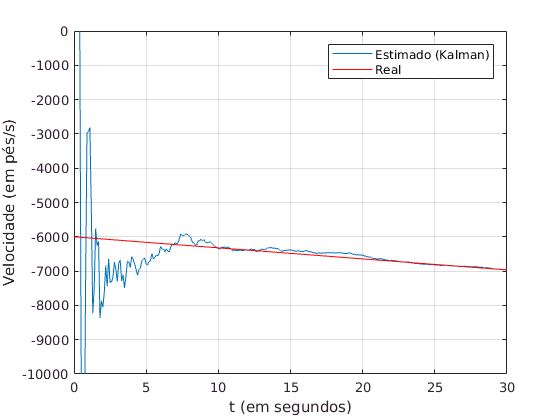


figure;
plot(t, xd_end, t, v, 'r')
legend('Estimado (Kalman)', 'Real');
xlabel('t (s)');
ylabel('Velocidade (pés/s)');
axis([0 Ttotal -10000 0])
grid;

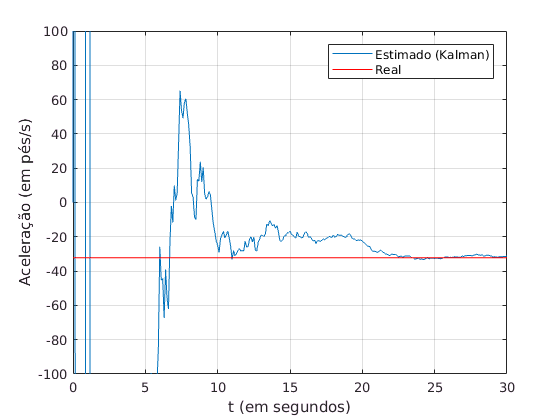


figure;
G2 = -g*linspace(1, 1 ,max(size(x)));
plot(t, xdd_end, t, G2, 'r')
legend('Estimado (Kalman)', 'Real');
xlabel('t (em segundos)');
ylabel('Aceleração (em pés/s)');
ylim([-100 100]);
grid;

Perceba que o Filtro de Kalman conseguiu fazer uma boa estimação do meu sistema.